
    %% 参数设置
    fs = 22000;             % 采样频率
    N = 22000;              % 信号长度
    a = 1;                  % 幅度
    phi = 0;                % 相位
    gamma = (3*pi/4 - pi/8) / (2 * N);  % 从题目公式推导
    sigma_w = 0.1;          % 噪声标准差

    n = 0:N-1;
    x_clean = a * cos(gamma * n.^2 + phi);
    w = sigma_w * randn(1, N);
    x_noisy = x_clean + w;

    %% 局部选取窗口做频率估计
    n0 = 10000;             % 中心点
    W = 400;                % 窗口长度（共 201 点）
    idx = (n0 - W/2):(n0 + W/2);
    x_local = x_noisy(idx);

    %% 零填充 FFT 增强分辨率
    N_fft = 4096;
    X = fft(x_local, N_fft);
    mag = abs(X(1:N_fft/2));
    [~, max_idx] = max(mag);
    f_est = (max_idx - 1) / N_fft * fs;  % Hz 单位
    omega_est = 2 * pi * f_est;          % rad/s

    %% 理论瞬时频率
    omega_theory = 2 * gamma * n0;
    f_theory = omega_theory / (2*pi) * fs;

    fprintf('瞬时频率估计值 f = %.2f Hz\n', f_est);

瞬时频率估计值 f = 3125.98 Hz


    fprintf('理论值 f = %.2f Hz\n', f_theory);

理论值 f = 3125.00 Hz


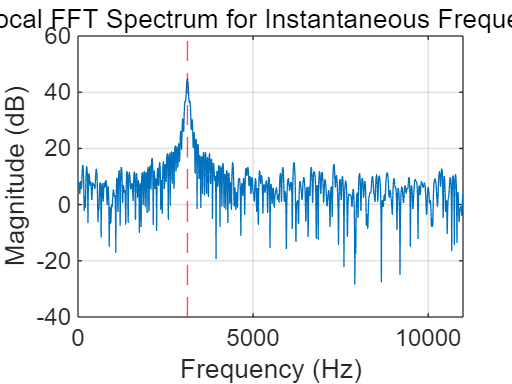


   %% 画图
figure;
plot((0:length(mag)-1) * fs / N_fft, 20*log10(mag));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Local FFT Spectrum for Instantaneous Frequency');
grid on;

% 添加竖线表示频率估计点
hold on;
xline(f_est, 'r--',  ...
    'LabelVerticalAlignment','bottom', ...
    'LabelHorizontalAlignment','right');
hold off;